# Visualize vehicle trajectories with Birdeye Scope

- First, simulate the vehicles' driving scenario in MOBATSim. The bird-eye scope doesn't allow the vehicle to stay on halt. So please set the appropriate scenario and the simulation time, to make sure any vehicle won't stop halfway.

%startingPoints =    [84 86 15 15 15 15 15 15 15 15];
%destinationPoints = [83 51 14 14  14  14 14 14 14 14];
%maxSpeeds = [7 20 8 10 14 20 10 12 10 10];

          2. "ToWorkspace" block needs to be added to all the vehicle model in Vehicle Kinematic 3DOF Single Track block in "Simulink Models/MOBATSim.slx", set the sample time as "Sim_Ts" :

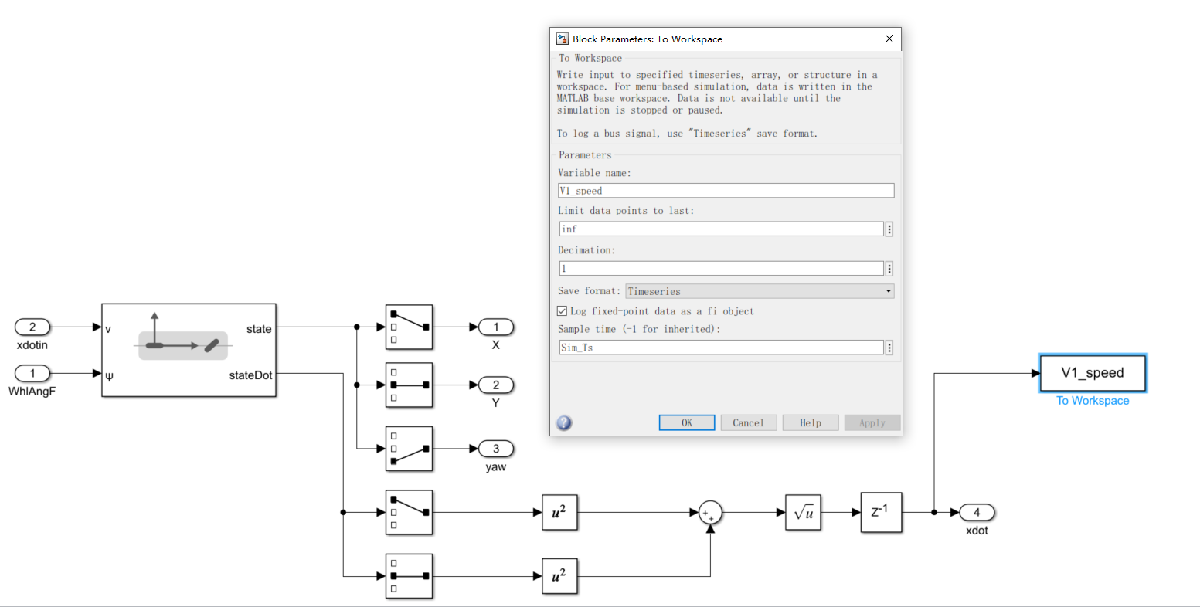

    3.Then run the simulation, stop time is "Sim_t".

    4. Load map in function "scenario_map_v1.m" before the load the vehicle data the same command is used in "openScenarioInApp.m" for 3D visualization as well.

MOBATKent_Scenario = scenario_map_v1();

    5. Go into 'run_Bird_eye_view.m', replace line 597 'temp = evalin('base','ans');' with load('ans.mat');

% load('vehicleTrajectories.mat'); % Not necessary anymore This MLX needs
% to be updated.
% temp = evalin('base','ans');

Delete all 'temp.'

egoVehicle = vehicle(scenario, ...
    'ClassID', 2, ...
    'Position', [-V2_translation.Data(1,3) -V2_translation.Data(1,1) 0]);

Unrecognized function or variable 'scenario'.

waypoints = [-V2_translation.Data((1:step_length:end),3) -V2_translation.Data((1:step_length:end),1) V2_translation.Data((1:step_length:end),2)];
speed = V2_speed.Data(1:step_length:end);
trajectory(egoVehicle, waypoints, speed);

 6. Add the command to open the Simulink Model for the ScenarioReader block and the Bird-Eye View visualization.

 open('BirdsEyeViewModel.slx');   

 7. Next, run "run_Bird_eye_view.m" and open the " ScenarioAnimation.slx" automatically .

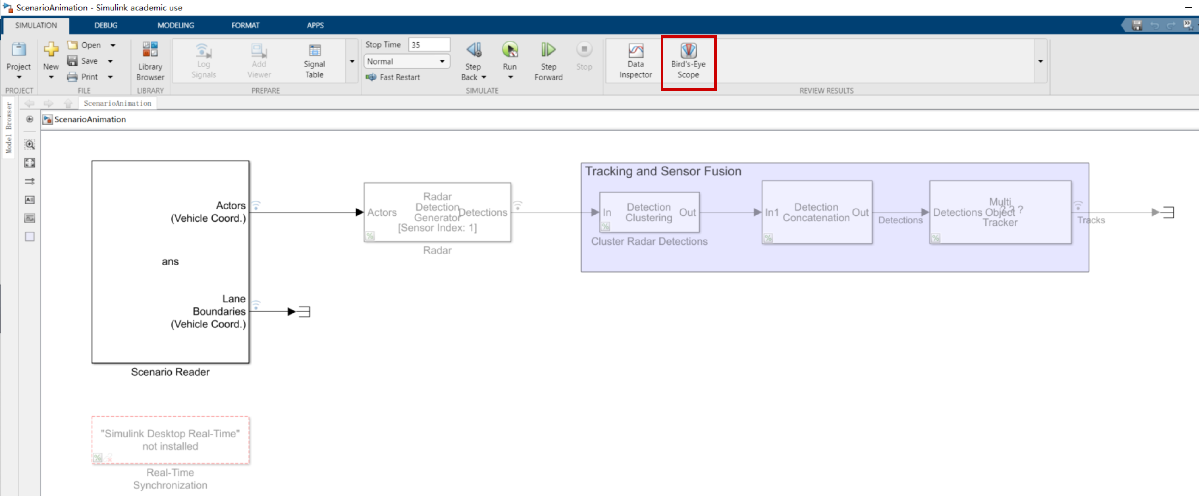

7. Next, open Bird's-eye Scope, do as follow:

-  click button "Find Signals"

-  clikc button "run" , the trajectories are visualized.

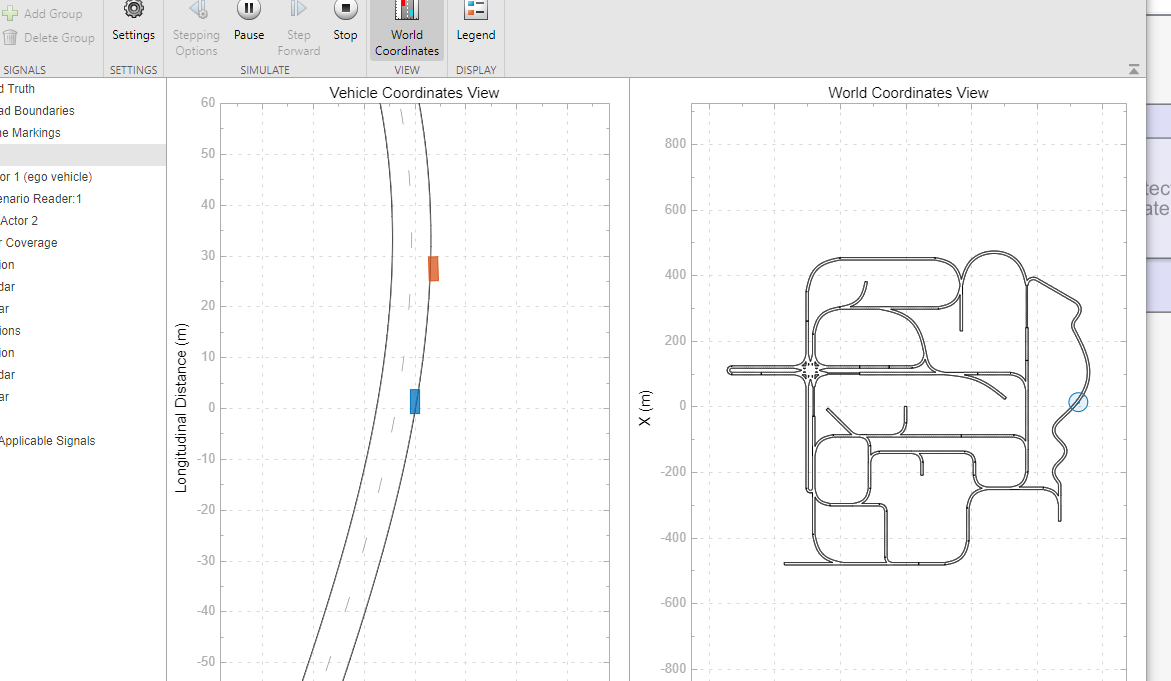

## Or for the simplicity, you can do like this:

- Run the whole MOBATSim project (choose appropriate scenario and simulation time to make sure the vehicles won't stop on half way)

- After all the data are in the workspace, run "run_Bird_eye_view.m"

- Open Bird's-Eye Scope App

- Click the button "Find Signals"

- Click the button "run", the trajectories are visualized.

- if you want to change the ego vehicle, just put the code of the corresponding vehicle to the first place in "run_Bird_eye_view.m".

- After that, if you want to see the 3D visualization in Unreal Engine, just run the"openScenarioInApp.m", this script is similar with "run_Bird_eye_view.m", but open the scenario in drivingScenarioDesigner in the end.

    drivingScenarioDesigner(MOBATKent_Scenario);

        8.In this App, click "3D Display" and choose "View Simulation in 3D Display", then click the button "run".

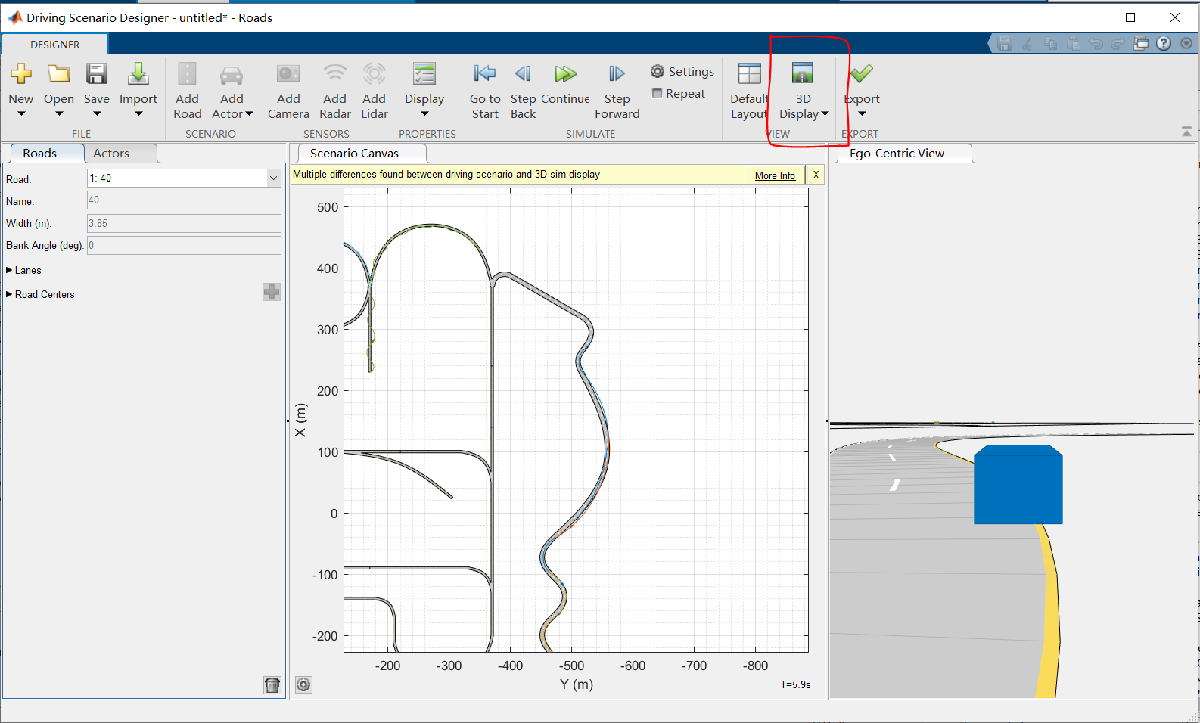

          9. Then you will  see the simulation in Unreal Engine:

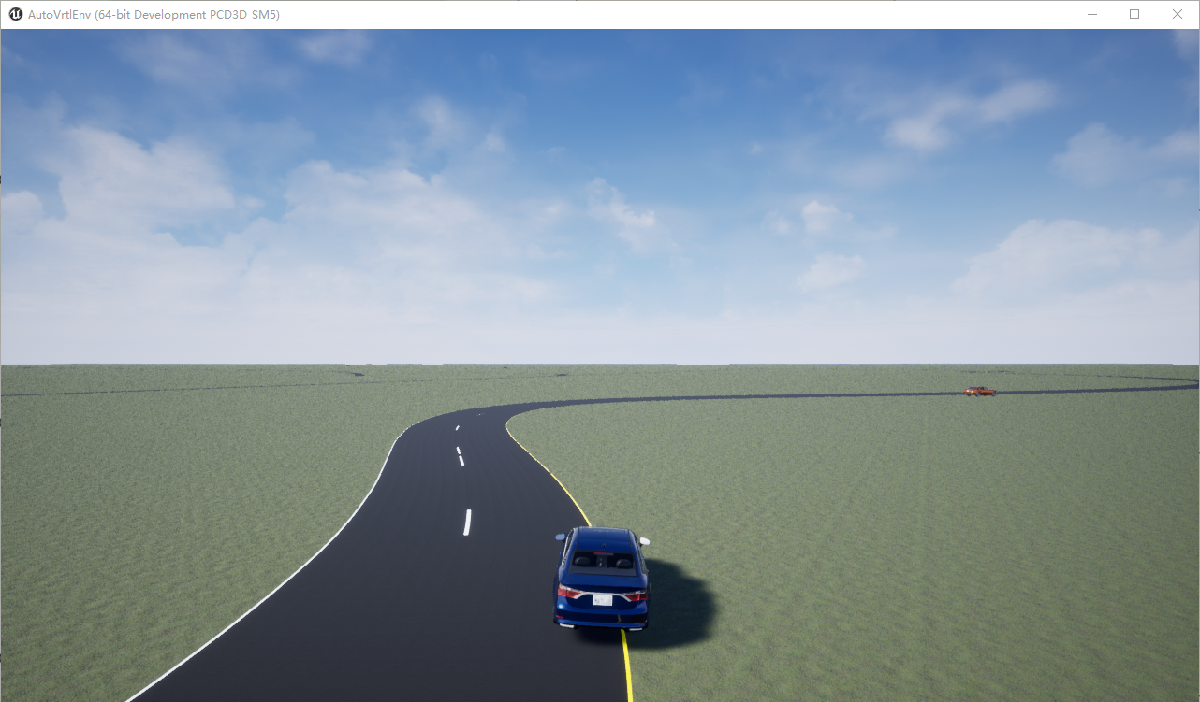

           10. Please notice that, for both 2D and 3D visualization, the simulation should run first.